# КУМС. ЛР 5. 

Денис Кирбаба R3438

#### 1. Параметры по вариантам

% ob.R = 10 + unifrnd(-1,1);  % сопротивление обмоток двигателя
% ob.L = 0.02 + unifrnd(-0.01,0.01);  % индуктивность обмоток двигателя
% ob.J = 100 + unifrnd(-10,10);  % момент инерции
% ob.Ce = 2;  % константа противо-ЭДС
% ob.Cm = ob.Ce;  % константа по моменту
% ob.kdw = 180/pi;  % коэффициент передачи датчика скорости (пересчет из радиан в градусы)
% save('data.mat','ob')

load("data.mat")

#### 2. Синтез системы с использованием "метода переоборудования"

**а) Передаточная функция объекта управления**

syms ia ua Md wd ea  % ток, напряжение, момент, скорость, противо-ЭДС
syms L R J Ce  % индуктивность, сопротивление, момент инерции, коэффициент противо-ЭДС
syms dia dwd  % производные по току и по скорости

eq(1) = ua - ea == L*dia + R*ia;  % уравнение для электрической части
eq(2) = J*dwd == Md;  % уравнение для механической части
eq(3) = Md == Ce*ia;
eq(4) = ea == Ce*wd;

S = solve(eq,[dia dwd Md ea]);
disp(collect(S.dia,[ia wd ua]))

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,\mathrm{wd}+\frac{\mathrm{ua}}{L}$$

disp(collect(S.dwd,[ia wd ua]))

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A = [-R/L -Ce/L;
     Ce/J 0];
B = [1/L; 0];
C = [0 1];
D = 0;

syms s
Wwa = C*(s*eye(2)-A)^-1*B+D;
disp(collect(Wwa))

$$\frac{\mathrm{Ce}}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

syms T1 T2 Kob
Wsmp = Kob/((T1*s+1)*(T2*s+1))

$$Wsmp = \frac{\mathrm{Kob}}{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}$$

disp(collect(expand(Wsmp),s))

$$\frac{\mathrm{Kob}}{\left(T_{1}\,T_{2}\right)\,s^{2}+\left(T_{1}+T_{2}\right)\,s+1}$$

eqn(1) = T1*T2 == J*L/Ce^2;
eqn(2) = T1+T2 == J*R/Ce^2;
S2 = solve(eqn,[T1 T2]);
S2.T1

$$ans = \left(\begin{array}{c} \frac{J\,R}{{\mathrm{Ce}}^{2}}-\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}}+\frac{J\,R}{{\mathrm{Ce}}^{2}} \end{array}\right)$$

S2.T2

$$ans = \left(\begin{array}{c} \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ -\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}} \end{array}\right)$$

ob.T2 = ((-ob.J*(4*ob.L*ob.Ce^2 - ob.J*ob.R^2))^(1/2) + ob.J*ob.R)/(2*ob.Ce^2);
ob.T1 = -((-ob.J*(4*ob.L*ob.Ce^2 - ob.J*ob.R^2))^(1/2) - ob.J*ob.R)/(2*ob.Ce^2);
disp(ob.T1)

    0.0026



disp(ob.T2)

  245.9089



ob.Kob = ob.kdw/ob.Ce;

**б) Расчет регулятора скорости**

syms Tu
T1 = Tu;
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = Wol/Wob

$$Wreg = \frac{T_{2}\,s+1}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s}$$

disp(simplify(collect(Wreg,s)))

$$\frac{T_{2}\,s+1}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s}$$

**в) Моделирование работы системы, настроенной на технический оптимум**

To=0.1Tu

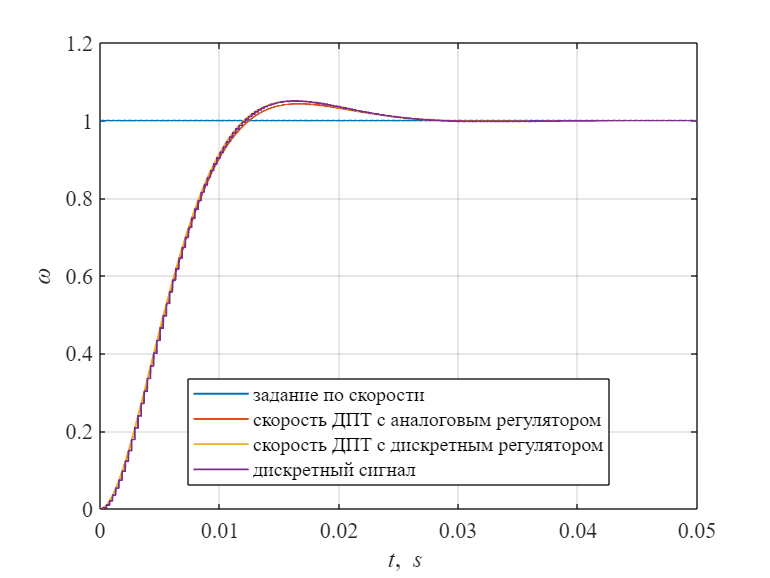

Tmdl = 1;

spl.Tu = ob.T1;
To = 0.1*spl.Tu;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

warning off
SimNew = sim('lab5p1b.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.05])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 4.0*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.3*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 5.0%


To=Tu

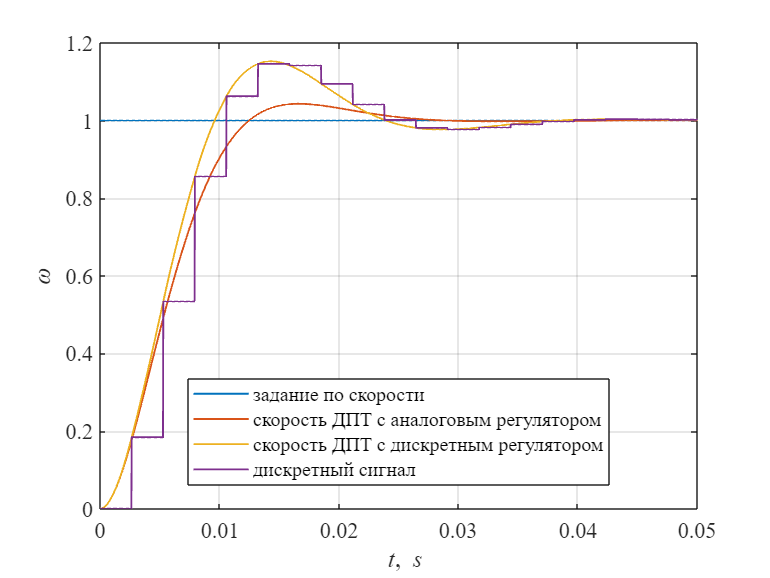

Tmdl = 1;

spl.Tu = ob.T1;
To = spl.Tu;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

warning off
SimNew = sim('lab5p1b.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.05])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 3.4*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 7.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 15.3%


#### 3. **Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т****1 ****≈ Т****0****,**  **Т****2 ****>> Т****0 ****, ε = 0.**

**а) Аппроксимация апериодическим звеном**

Tmdl = 1;
for i = 1:10
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab5p3.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

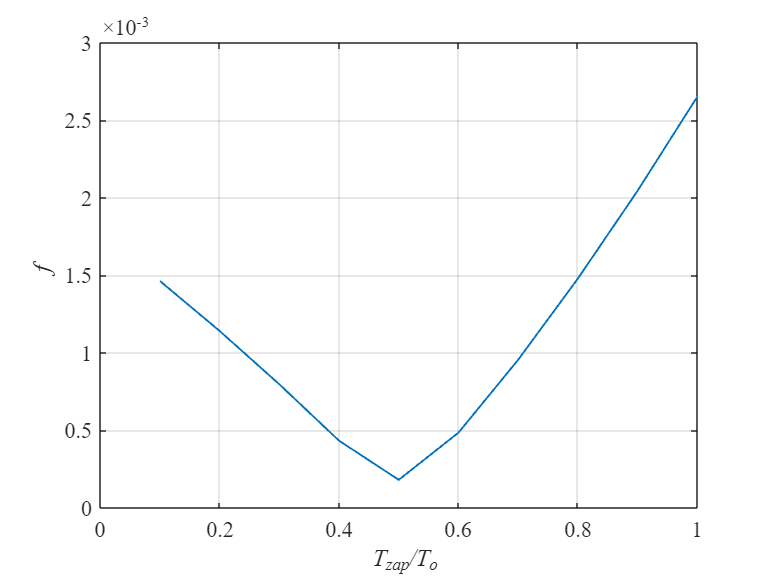

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

**б) Синтез цифрового ПИ-регулятора**

To=1T1

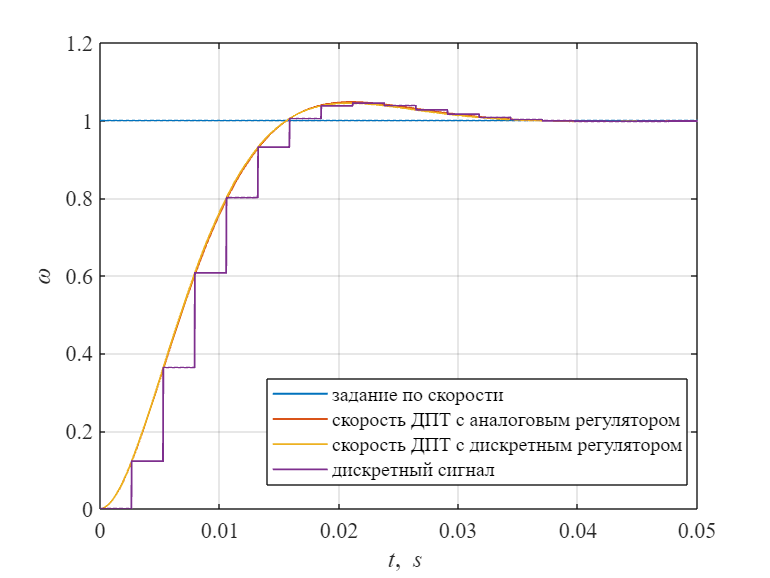

Tmdl = 1;

To = 1*ob.T1;
spl.Tz = 0.5*To;
spl.Tu = ob.T1+spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

warning off
SimNew = sim('lab5p3.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.05])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 3.5*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 3.5*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 4.5%


To=2T1

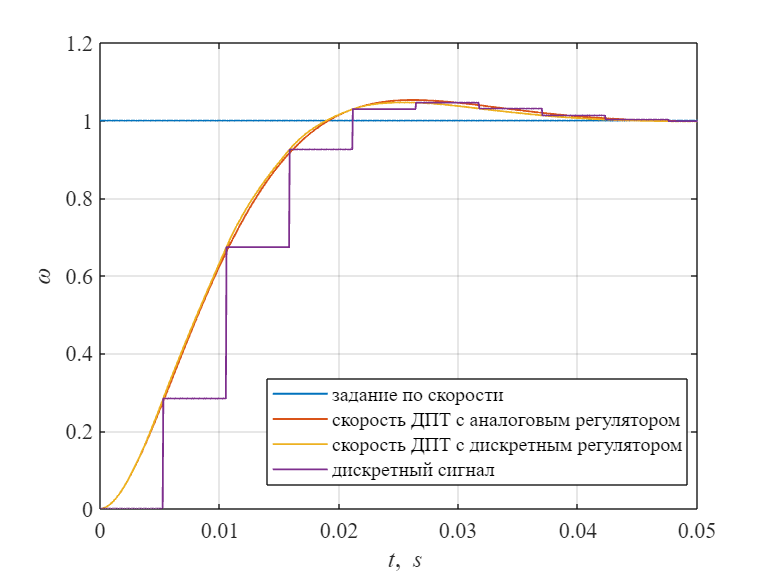

Tmdl = 1;

To = 2*ob.T1;
spl.Tz = 0.5*To;
spl.Tu = ob.T1+spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

warning off
SimNew = sim('lab5p3.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.05])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 3.1*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 3.1*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 4.7%


#### 4. **Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 >> Т0,  Т2 >> Т0 , ε = 0.**

**а) Расчет регулятора скорости**

syms Tu
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = Wol/Wob

$$Wreg = \frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s\,\left(\mathrm{Tu}\,s+1\right)}$$

disp(simplify(collect(Wreg,s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s\,\left(\mathrm{Tu}\,s+1\right)}$$

**б) Моделирование работы системы настроенной на технический оптимум**

To = 0.1*T1

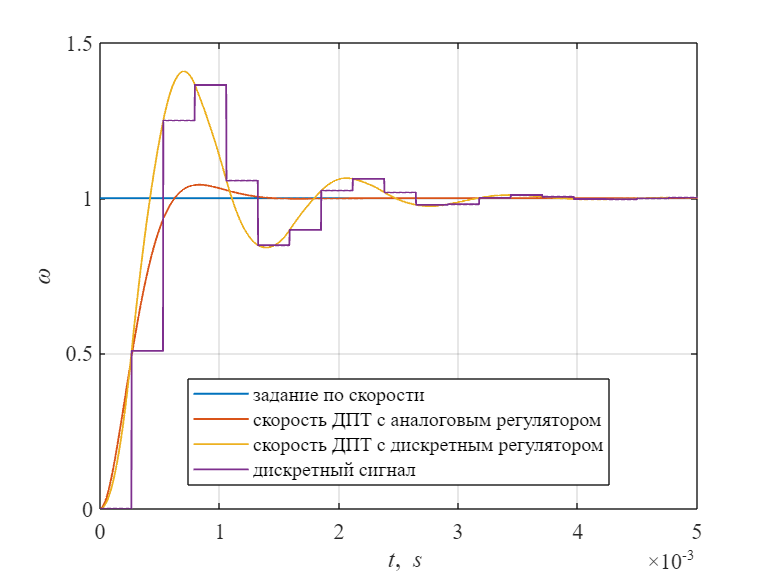

Tmdl = 1;

To = 0.1*ob.T1;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;

warning off
SimNew = sim('lab5p4.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.005])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 3.0*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 16.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 40.8%


**в) Аппроксимация апериодическим звеном**

Tmdl = 0.01;
for i = 1:10
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab5p4b.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

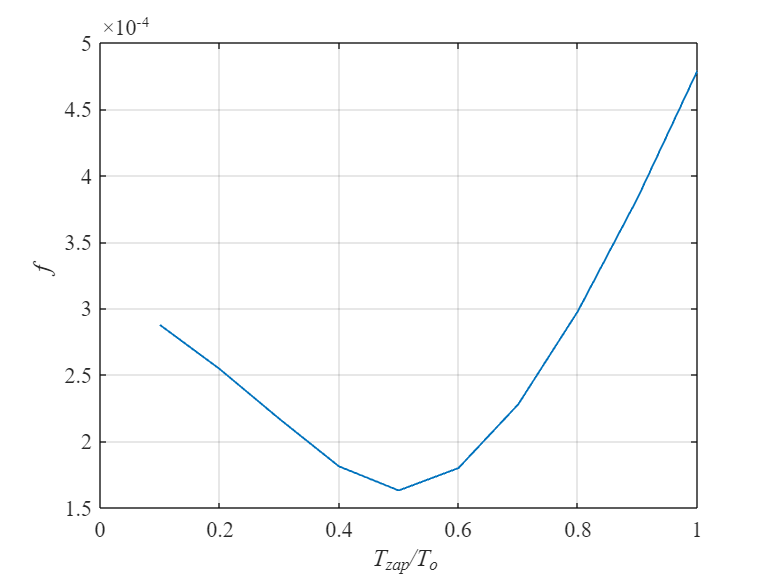

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

**г) Синтез цифрового регулятора скорости "методом переоборудования"**

To = 0.1*T1

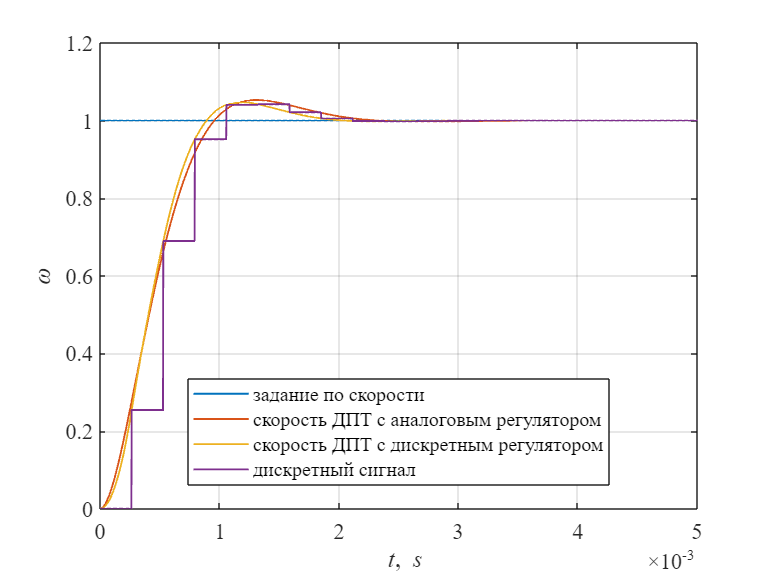

Tmdl = 0.01;

To = 0.1*ob.T1;
spl.Tz = 0.5*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur+spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;

warning off
SimNew = sim('lab5p4b.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.005])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 3.0*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 3.0*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 4.7%


#### 5. **Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 >> Т0,  Т2 >> Т0 , ε = T0.**

**а) Аппроксимация апериодическим звеном**

Tmdl = 0.01;
for i = 1:20
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab5p5.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

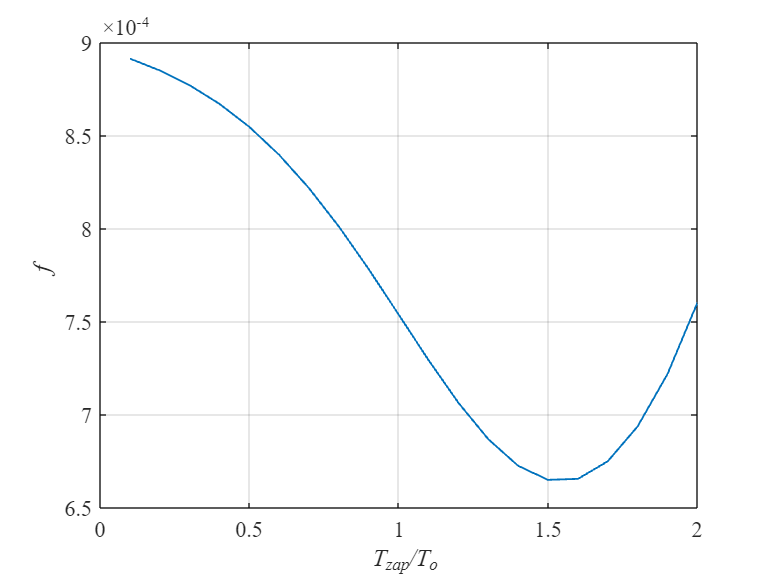

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

**б) Синтез цифрового регулятора скорости "методом переоборудования"**

To = 0.1*T1

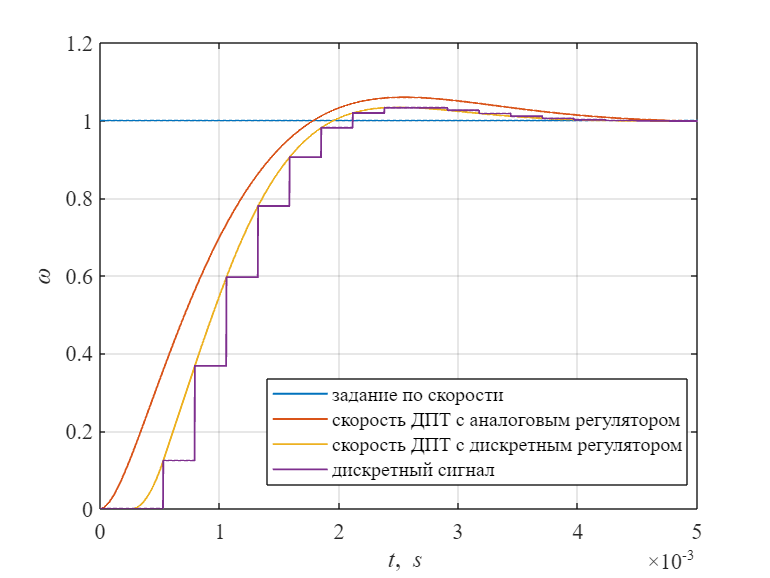

Tmdl = 0.01;

To = 0.1*ob.T1;
spl.Tz = 1.55*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur+spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;

warning off
SimNew = sim('lab5p5.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.005])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 3.2*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 3.2*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 3.4%
